When the simulation length is longer than approximately a month, the viewer does not work properly. Here you can find an example of plotting the trajectories with MATLAB 3D plots.

area = 0;       % m2
ref = 1.5;      % NA
initMass = 10;  % kg
earthRadius = 6378136.3;    % m
% [sma,ecc,inc,RAAN,aop,true_an] = deal(10000e3+earthRadius, 0.3, 25, 0, 100, 25);
p = 200e3+earthRadius; f = 1000e3+earthRadius; sma = (p+f)/2; ecc = (f-p)/(f+p);
[inc,RAAN,aop,true_an] = deal(5, 0, 135, -20);
startDate = juliandate(datetime(2024, 01, 01));
burnOverride = 0;
thrustingThreshold = sma*(1-ecc)*1.5;
thrust = 0.001;

Simulate the satellite.

tf = 30; tf = tf * 30 * 24 * 3600;
tic;
simOut = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.1107s


toc

Elapsed time is 20.012504 seconds.


tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
ttSat = retime(ttSat,'minutely');
tsSatVel = simOut.yout{2}.Values;
ttSatVel  = timeseries2timetable(tsSatVel);
ttSatVel = retime(ttSatVel, 'minutely');
tsMoon = simOut.yout{5}.Values;
ttMoon = timeseries2timetable(tsMoon);
ttMoon = retime(ttMoon,'minutely');

Plot the simulation in ICRF.

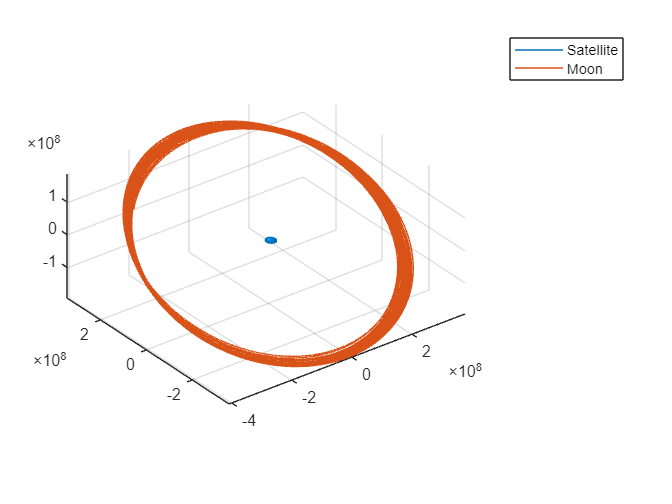

tic
figure
[X,Y,Z] = sphere();
p = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(p, 'edgecolor', 'none', 'FaceColor', [0,150,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1), ttSat.Data(:,2), ttSat.Data(:,3), DisplayName='Satellite')
plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), DisplayName='Moon')
legend
axis equal
daspect([1 1 1])

% lim = [-8 8]*1e8;
% xlim(lim)
% ylim(lim)
% zlim(lim)
toc

Elapsed time is 0.130458 seconds.


We analyze the changes produced in the satellite's orbit.

r = ttSat(1,1).Data;
v = ttSatVel(1,1).Data;
[sma1,ecc1,inc1,RAAN1,aop1] = state2class(r, v, 1)

sma1 = 6.9781e+06

ecc1 = 0.0573

inc1 = 5.0000

RAAN1 = 360

aop1 = 135.0000


r = ttSat(end,end).Data;
v = ttSatVel(end,end).Data;
[sma2,ecc2,inc2,RAAN2,aop2] = state2class(r, v, 1)

sma2 = 1.4899e+07

ecc2 = 0.3620

inc2 = 4.9725

RAAN2 = 3.9686

aop2 = 130.9718


smaDev = (sma1-sma2)/sma1

smaDev = -1.1351

eccDev = (ecc1-ecc2)/ecc1

eccDev = -5.3148

incDev = (inc1-inc2)/inc1

incDev = 0.0055

RAANDev = (RAAN1-RAAN2)/RAAN1

RAANDev = 0.9890

aopDev = (aop1-aop2)/aop1

aopDev = 0.0298